clear all, clc

%Gráficos de nuestras mediciones
first = load('Caminando con telefono en la bolsa izquierda.mat')

first = struct with fields:
    Acceleration: [4047×3 timetable]


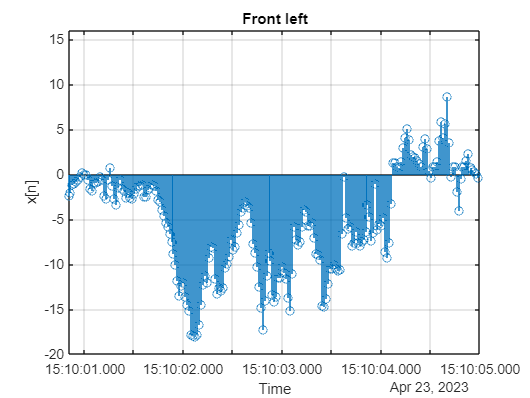


stem(first.Acceleration.Timestamp,first.Acceleration.X);
title 'Front left'
xlabel 'Time'
ylabel 'x[n]'
xlim([datetime(2023,4,23,15,10,00,843)...:0,1:
      datetime(2023,4,23,15,10,05,000)]);
ylim([-20 16])
grid on



second = load('Caminando bolsa derecha.mat')

second = struct with fields:
    Acceleration: [6126×3 timetable]


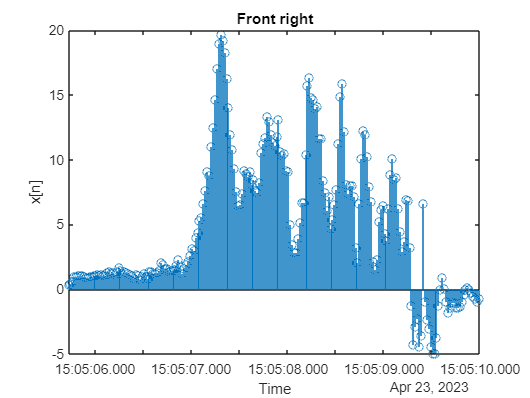

 
stem(second.Acceleration.Timestamp,second.Acceleration.X);
title 'Front right'
xlabel 'Time'
ylabel 'x[n]'
xlim([datetime(2023,4,23,15,05,05,729)...:0,1:
      datetime(2023,4,23,15,05,10)]);

 
third = load('Caminando con telefono en la bolsa izquierda trasera.mat')

third = struct with fields:
    Acceleration: [4850×3 timetable]


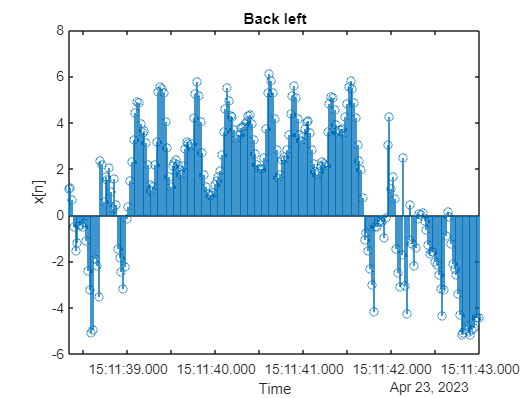

 
stem(third.Acceleration.Timestamp,third.Acceleration.X);
title 'Back left'
xlabel 'Time'
ylabel 'x[n]'
xlim([datetime(2023,4,23,15,11,38,331)...:0,1:
      datetime(2023,4,23,15,11,43)]);


fourth = load('Caminando con telefono en la bolsa trasera derecha.mat')

fourth = struct with fields:
    Acceleration: [3463×3 timetable]


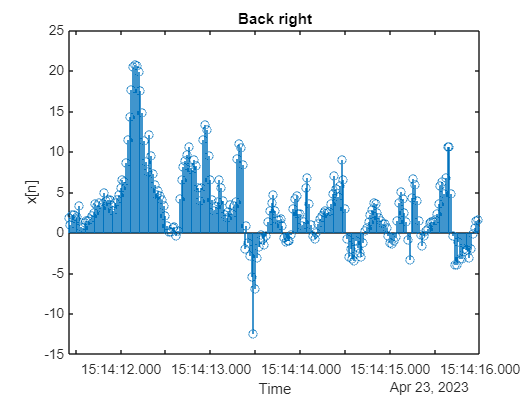


stem(fourth.Acceleration.Timestamp,fourth.Acceleration.X);
title 'Back right'
xlabel 'Time'
ylabel 'x[n]'
xlim([datetime(2023,4,23,15,14,11,419)...:0,1:
      datetime(2023,4,23,15,14,16)]);


fifth = load('Caminando con Telefono en la mano.mat')

fifth = struct with fields:
    Acceleration: [3404×3 timetable]


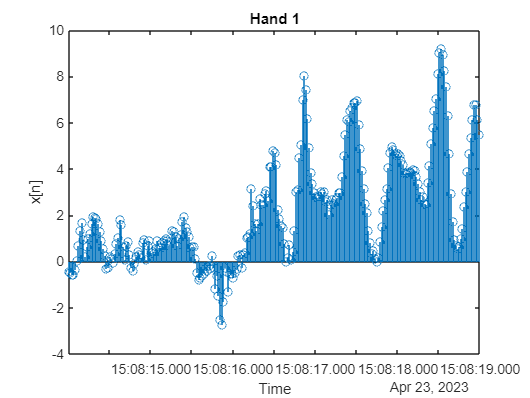

 
stem(fifth.Acceleration.Timestamp,fifth.Acceleration.X);
title 'Hand 1'
xlabel 'Time'
ylabel 'x[n]'
xlim([datetime(2023,4,23,15,08,14,007)...:0,1:
      datetime(2023,4,23,15,08,19)]);

 
sixth = load('Telefono en la mano.mat')

sixth = struct with fields:
    Acceleration: [3015×3 timetable]


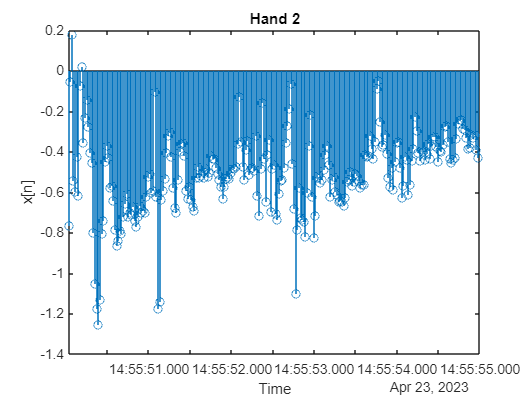

 
stem(sixth.Acceleration.Timestamp,sixth.Acceleration.X);
title 'Hand 2'
xlabel 'Time'
ylabel 'x[n]'
xlim([datetime(2023,4,23,14,55,50,035)...:0,1:
      datetime(2023,4,23,14,55,55)]);

 
seventh = load('Caidas.mat')

seventh = struct with fields:
    Acceleration: [3429×3 timetable]


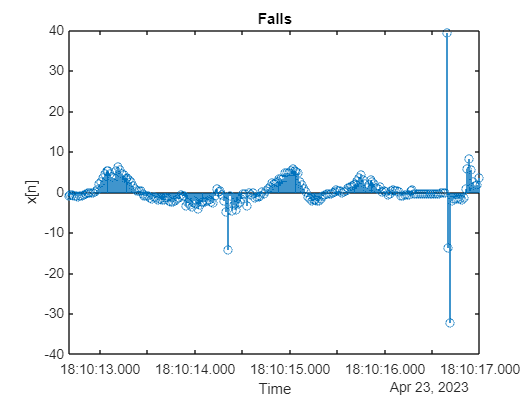

 
stem(seventh.Acceleration.Timestamp,seventh.Acceleration.X);
title 'Falls'
xlabel 'Time'
ylabel 'x[n]'
xlim([datetime(2023,4,23,18,10,12,668)...:0,1:
      datetime(2023,4,23,18,10,17)]);

 
load('Uso Real.mat');  % carga el archivo .mat en una variable
Acceleration          % muestra el contenido de la variable "mi_matriz"

Acceleration = 21543×3 timetable
           Timestamp               X           Y         Z   
    ________________________    ________    _______    ______

    23-Apr-2023 18:29:34.308    -0.44278     1.0487    8.3495
    23-Apr-2023 18:29:34.328    -0.44877     1.2195     9.897
    23-Apr-2023 18:29:34.348    -0.32767     1.1432    10.284
    23-Apr-2023 18:29:34.368    -0.48978    0.98241    9.2074
    23-Apr-2023 18:29:34.388    -0.32453     1.1221    10.226
    23-Apr-2023 18:29:34.408    -0.39638    0.98585    9.6943
    23-Apr-2023 18:29:34.428    -0.37542     1.0707    9.7973
    23-Apr-2023 18:29:34.448    -0.33725     1.0421    9.9298
    23-Apr-2023 18:29:34.468     -0.3856     1.0742    9.


eight = load('Uso Real.mat')

eight = struct with fields:
    Acceleration: [21543×3 timetable]


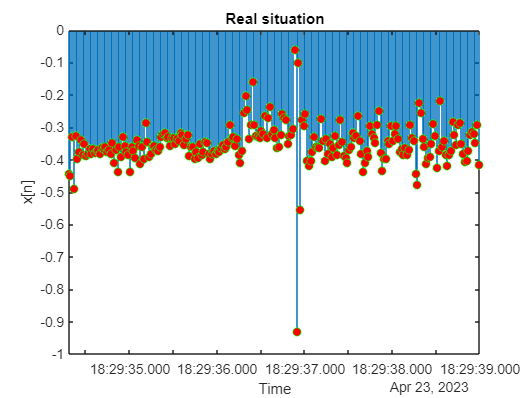

stem(eight.Acceleration.Timestamp,eight.Acceleration.X,'LineStyle','-','MarkerFaceColor','red','MarkerEdgeColor','green');
title 'Real situation'
xlabel 'Time'
ylabel 'x[n]'
xlim([datetime(2023,4,23,18,29,34,308)...:0,1:
      datetime(2023,4,23,18,29,39)]);

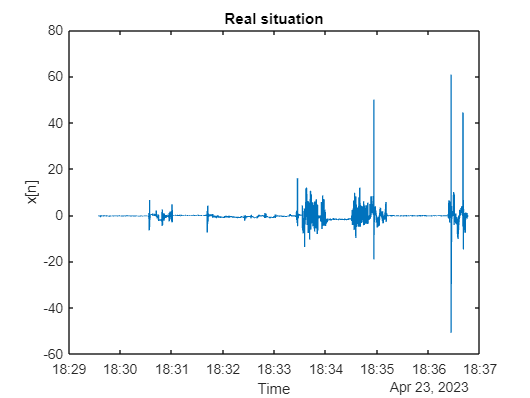

plot(eight.Acceleration.Timestamp,eight.Acceleration.X)
title 'Real situation'
xlabel 'Time'
ylabel 'x[n]'


%Ajuste polinómico
time = 1:1:21543;
p = polyfit(time,eight.Acceleration.X,50);

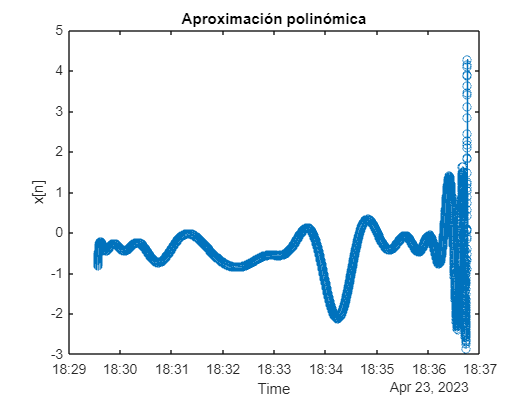

y = polyval(p,time);


plot(eight.Acceleration.Timestamp,y,'-O')
title 'Aproximación polinómica'
xlabel 'Time'
ylabel 'x[n]'

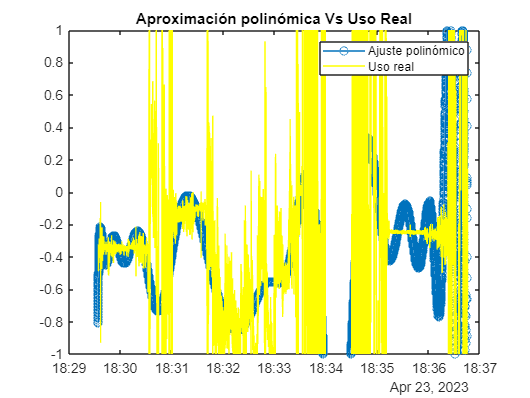


plot(eight.Acceleration.Timestamp,y,'-o',eight.Acceleration.Timestamp,eight.Acceleration.X,"y")
title 'Aproximación polinómica Vs Uso Real'
legend('Ajuste polinómico','Uso real')
ylim([-1 1])



%FFT
F = 500;
T = 1/F;
L = 100;
X = fft(y)  %transformada rapida de Fourier

X = 1.0e+03 *

  -9.7534 + 0.0000i   2.2540 - 0.0399i  -0.1296 + 1.3187i  -2.1219 + 0.4807i   3.1821 - 1.5121i  -0.7241 + 2.0574i  -2.8957 - 1.2172i   1.8512 + 0.1881i  -0.7500 + 1.8570i  -0.7757 - 0.9303i  -0.0491 - 0.6772i  -0.2993 - 0.4795i  -0.3473 - 0.3822i  -0.3492 - 0.3791i  -0.2254 - 0.5410i   0.0833 - 0.7011i   0.4764 - 0.7068i   0.8153 - 0.5351i   1.0158 - 0.2489i   1.0605 + 0.0701i   0.9749 + 0.3582i   0.8014 + 0.5800i   0.5820 + 0.7239i   0.3502 + 0.7939i   0.1294 + 0.8018i  -0.0664 + 0.7622i  -0.2303 + 0.6896i  -0.3608 + 0.5964i  -0.4592 + 0.4922i  -0.5284 + 0.3847i  -0.5724 + 0.2790i  -0.5952 + 0.1789i  -0.6007 + 0.0867i  -0.5926 + 0.0034i  -0.5737 - 0.0703i  -0.5468 - 0.1342i  -0.5145 - 0.1888i  -0.4785 - 0.2347i  -0.4403 - 0.2727i  -0.4009 - 0.3037i  -0.3610 - 0.3282i  -0.3214 - 0.3468i  -0.2830 - 0.3602i  -0.2460 - 0.3691i  -0.2109 - 0.3743i  -0.1777 - 0.3763i  -0.1465 - 0.3758i  -0.1173 - 0.3730i  -0.0902 - 0.3685i  -0.0650 - 0.3626i


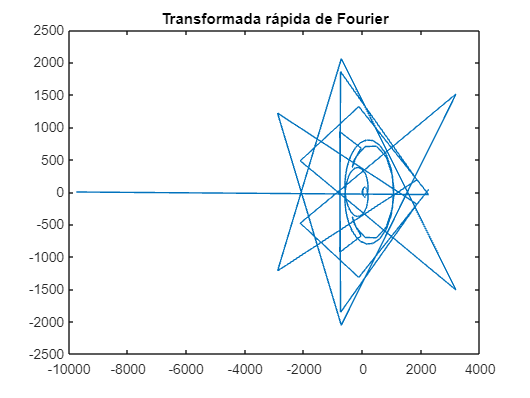

plot(real(X),imag(X))
title 'Transformada rápida de Fourier'


%Espectro unilateral
P2 = abs(X/L);
P1 = P2(1:L/2+1);
P1 (2:end-1) = 2*P1(2:end-1)

P1 =    97.5341   45.0868   26.5007   43.5134   70.4625   43.6227   62.8212   37.2149   40.0550   24.2253   13.5789   11.3046   10.3290   10.3085   11.7214   14.1204   17.0479   19.5048   20.9175   21.2566   20.7722   19.7846   18.5769   17.3542   16.2425   15.3016   14.5415   13.9405   13.4629   13.0722   12.7360   12.4302   12.1390   11.8512   11.5590   11.2610   10.9604   10.6596   10.3590   10.0584    9.7571    9.4569    9.1607    8.8719    8.5922    8.3231    8.0662    7.8203    7.5869    7.3687


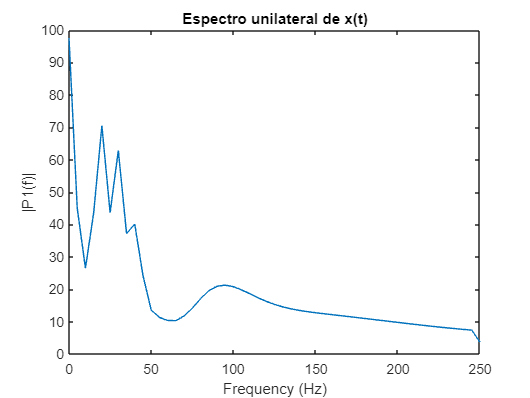

f = F*(0:(L/2))/L;
plot(f,P1)
title 'Espectro unilateral de x(t)'
xlabel 'Frequency (Hz)'
ylabel '|P1(f)|'